# Load Data

load('MatlabData/testData.mat')
data

data = struct with fields:
             setname: 'test epochs'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: [4×150 char]
              nbchan: 64
              trials: 22
                pnts: 480
               srate: 160
                xmin: -1
                xmax: 1.9937
               times: [1×480 double]
                data: [64×480×22 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [64×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×22 struct]
             urevent: [1×30 struct]
    eventdescription: {''  ''  ''  ''  ''  ''}
               epoch: [1×22 struct]
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1 struct]
            spec

## Organize Data

im = im(:,:,1) =

    0.4138    0.4005    0.4029    0.4037    0.4037    0.4036    0.3976    0.4695    0.5744    0.5741    0.5736    0.5749    0.5748    0.5748    0.5786    0.5201    0.4694    0.4651    0.4701    0.4705    0.4704    0.4707    0.4698    0.4353    0.4279    0.4288    0.4288    0.4288    0.4288    0.4288    0.4290    0.4321    0.4326    0.4325    0.4325    0.4322    0.4348    0.4329    0.4506    0.4992    0.4981    0.4980    0.4980    0.4978    0.5007    0.4951    0.5166    0.5363    0.5354    0.5354    0.5354    0.5351    0.5263    0.5281    0.2551    0.1777    0.1865    0.1865    0.1865    0.1866    0.1732    0.2543    0.4917    0.4921    0.4906    0.4906    0.4905    0.4913    0.4929    0.4487    0.4184    0.4194    0.4196    0.4196    0.4196    0.4199    0.4156    0.4454    0.4619    0.4664    0.4662    0.4662    0.4660    0.4663    0.4822    0.5491    0.5565    0.5549    0.5548    0.5548    0.5549    0.5579    0.5207    0.3949    0.3948    0.3953    0.3952    0.3952  

im = im(:,:,1) =

    0.5624    0.5427    0.5531    0.5521    0.5522    0.5522    0.5739    0.3340   -0.0075    0.0119    0.0035    0.0032    0.0033    0.0032   -0.0159    0.2327    0.5021    0.4831    0.4838    0.4846    0.4845    0.4846    0.4844    0.4745    0.4723    0.4726    0.4726    0.4726    0.4726    0.4716    0.4774    0.5671    0.5802    0.5785    0.5785    0.5784    0.5817    0.5831    0.5756    0.5674    0.5682    0.5682    0.5682    0.5682    0.5645    0.5665    0.5706    0.5719    0.5717    0.5717    0.5717    0.5717    0.5697    0.5697    0.5621    0.5616    0.5618    0.5618    0.5618    0.5617    0.5634    0.5258    0.4199    0.4155    0.4165    0.4165    0.4165    0.4167    0.4158    0.4523    0.4768    0.4724    0.4726    0.4726    0.4726    0.4723    0.4729    0.4770    0.4802    0.4807    0.4806    0.4806    0.4807    0.4798    0.4847    0.5004    0.5032    0.5021    0.5022    0.5022    0.5022    0.5053    0.4738    0.3549    0.3464    0.3470    0.3470    0.3470  

im = im(:,:,1) =

    0.4413    0.4359    0.4349    0.4352    0.4351    0.4351    0.4347    0.4389    0.4487    0.4479    0.4504    0.4501    0.4501    0.4502    0.4554    0.3840    0.3038    0.3059    0.3099    0.3089    0.3089    0.3088    0.3094    0.3351    0.3407    0.3400    0.3400    0.3400    0.3400    0.3387    0.3464    0.4663    0.4838    0.4816    0.4816    0.4815    0.4808    0.4861    0.4748    0.4403    0.4413    0.4414    0.4414    0.4412    0.4442    0.4454    0.3053    0.2515    0.2569    0.2569    0.2569    0.2571    0.2531    0.2559    0.3324    0.3570    0.3551    0.3551    0.3551    0.3551    0.3531    0.3907    0.4866    0.4823    0.4816    0.4816    0.4816    0.4815    0.4775    0.5234    0.5557    0.5564    0.5561    0.5561    0.5560    0.5571    0.5604    0.4882    0.4477    0.4500    0.4501    0.4501    0.4502    0.4529    0.4246    0.2940    0.2844    0.2876    0.2874    0.2874    0.2874    0.2860    0.3023    0.3536    0.3518    0.3503    0.3504    0.3504  

im = im(:,:,1) =

    0.4345    0.4245    0.4241    0.4244    0.4243    0.4243    0.4168    0.5076    0.6299    0.6220    0.6206    0.6199    0.6200    0.6200    0.6200    0.6175    0.6168    0.6169    0.6169    0.6169    0.6169    0.6180    0.6141    0.4532    0.4185    0.4227    0.4227    0.4227    0.4227    0.4226    0.4231    0.4305    0.4316    0.4315    0.4315    0.4313    0.4337    0.4321    0.4485    0.4752    0.4756    0.4754    0.4754    0.4754    0.4740    0.4732    0.5108    0.5286    0.5271    0.5271    0.5271    0.5271    0.5239    0.5275    0.5050    0.4936    0.4946    0.4946    0.4946    0.4943    0.4871    0.5057    0.5494    0.5495    0.5494    0.5494    0.5495    0.5492    0.5623    0.3249    0.1730    0.1839    0.1838    0.1838    0.1837    0.1848    0.1662    0.5347    0.7101    0.6928    0.6930    0.6930    0.6930    0.6957    0.6713    0.5504    0.5423    0.5396    0.5397    0.5397    0.5395    0.5450    0.5079    0.3735    0.3653    0.3710    0.3707    0.3707  

im = im(:,:,1) =

    0.4387    0.4288    0.4355    0.4364    0.4363    0.4363    0.4406    0.3898    0.3181    0.3196    0.3222    0.3214    0.3215    0.3215    0.3242    0.2886    0.2510    0.2579    0.2580    0.2583    0.2583    0.2587    0.2572    0.1956    0.1823    0.1839    0.1839    0.1839    0.1839    0.1836    0.1852    0.2090    0.2125    0.2121    0.2121    0.2118    0.2157    0.2180    0.2269    0.2469    0.2469    0.2468    0.2468    0.2468    0.2403    0.2465    0.3012    0.3262    0.3238    0.3238    0.3238    0.3240    0.3219    0.3312    0.4469    0.4764    0.4733    0.4732    0.4732    0.4733    0.4804    0.4242    0.2806    0.2841    0.2848    0.2848    0.2848    0.2847    0.2754    0.4108    0.4962    0.4852    0.4853    0.4853    0.4853    0.4855    0.4948    0.3551    0.2879    0.2933    0.2934    0.2934    0.2935    0.2891    0.3184    0.4757    0.4859    0.4797    0.4802    0.4802    0.4802    0.4807    0.4751    0.4650    0.4652    0.4659    0.4659    0.4659  

im = im(:,:,1) =

    0.3487    0.3396    0.3313    0.3326    0.3325    0.3325    0.3246    0.4179    0.5506    0.5412    0.5480    0.5473    0.5473    0.5473    0.5473    0.5511    0.5523    0.5522    0.5522    0.5522    0.5522    0.5528    0.5506    0.4588    0.4390    0.4414    0.4414    0.4414    0.4414    0.4408    0.4439    0.4924    0.4994    0.4985    0.4985    0.4987    0.4959    0.4944    0.4951    0.5006    0.5011    0.5010    0.5010    0.5010    0.5021    0.5005    0.4133    0.3802    0.3835    0.3835    0.3835    0.3837    0.3836    0.3838    0.4554    0.4745    0.4726    0.4726    0.4725    0.4729    0.4755    0.4520    0.4046    0.4051    0.4053    0.4053    0.4053    0.4050    0.4018    0.4499    0.4803    0.4808    0.4806    0.4806    0.4807    0.4800    0.4747    0.5257    0.5505    0.5505    0.5503    0.5503    0.5504    0.5502    0.5492    0.5490    0.5505    0.5523    0.5522    0.5522    0.5523    0.5518    0.5408    0.5301    0.5293    0.5295    0.5295    0.5295  

im = im(:,:,1) =

    0.4122    0.3983    0.3951    0.3958    0.3957    0.3957    0.3897    0.4620    0.5684    0.5652    0.5668    0.5683    0.5682    0.5682    0.5695    0.5459    0.5252    0.5251    0.5269    0.5266    0.5266    0.5260    0.5279    0.6053    0.6220    0.6200    0.6200    0.6200    0.6200    0.6209    0.6157    0.5359    0.5243    0.5258    0.5258    0.5256    0.5268    0.5273    0.5136    0.4866    0.4872    0.4873    0.4873    0.4871    0.4836    0.4888    0.5287    0.5493    0.5473    0.5473    0.5473    0.5472    0.5438    0.5440    0.4769    0.4588    0.4606    0.4606    0.4606    0.4607    0.4624    0.4503    0.4143    0.4119    0.4120    0.4120    0.4120    0.4118    0.4071    0.5232    0.5964    0.5862    0.5863    0.5863    0.5863    0.5858    0.5844    0.5683    0.5595    0.5594    0.5594    0.5594    0.5594    0.5622    0.5377    0.4315    0.4273    0.4334    0.4331    0.4331    0.4331    0.4287    0.4606    0.5891    0.5906    0.5859    0.5863    0.5863  

im = im(:,:,1) =

    0.3576    0.3413    0.3364    0.3361    0.3361    0.3361    0.3360    0.3380    0.3388    0.3388    0.3391    0.3391    0.3391    0.3390    0.3301    0.4455    0.5772    0.5592    0.5723    0.5717    0.5717    0.5720    0.5710    0.5304    0.5216    0.5227    0.5227    0.5227    0.5227    0.5233    0.5194    0.4582    0.4493    0.4504    0.4504    0.4506    0.4503    0.4502    0.4636    0.4855    0.4846    0.4845    0.4845    0.4847    0.4844    0.4812    0.5531    0.5809    0.5786    0.5785    0.5785    0.5785    0.5816    0.5826    0.5825    0.5825    0.5825    0.5825    0.5824    0.5822    0.5928    0.5947    0.6117    0.6105    0.6105    0.6105    0.6105    0.6109    0.6124    0.5538    0.5139    0.5144    0.5147    0.5147    0.5146    0.5148    0.5152    0.5967    0.6341    0.6276    0.6278    0.6278    0.6278    0.6361    0.5725    0.2632    0.2505    0.2553    0.2553    0.2553    0.2553    0.2460    0.3264    0.6087    0.6108    0.6107    0.6105    0.6105  

im = im(:,:,1) =

    0.4244    0.4163    0.4113    0.4118    0.4118    0.4118    0.4089    0.4480    0.4954    0.4934    0.4944    0.4939    0.4940    0.4940    0.5029    0.3858    0.2516    0.2726    0.2671    0.2671    0.2671    0.2661    0.2697    0.4196    0.4519    0.4480    0.4480    0.4480    0.4480    0.4501    0.4381    0.2514    0.2241    0.2276    0.2276    0.2275    0.2231    0.2219    0.2491    0.3065    0.3051    0.3049    0.3049    0.3048    0.3094    0.3118    0.3482    0.3616    0.3598    0.3599    0.3599    0.3600    0.3578    0.3581    0.3414    0.3338    0.3345    0.3345    0.3345    0.3339    0.3316    0.3542    0.4212    0.4269    0.4266    0.4266    0.4265    0.4276    0.4330    0.3518    0.2957    0.3007    0.3009    0.3009    0.3009    0.3008    0.3024    0.3574    0.3901    0.3960    0.3954    0.3954    0.3953    0.3980    0.3806    0.2859    0.2814    0.2858    0.2855    0.2855    0.2857    0.2803    0.3179    0.4540    0.4637    0.4604    0.4606    0.4606  

im = im(:,:,1) =

    0.4207    0.4116    0.4064    0.4066    0.4066    0.4066    0.4040    0.4400    0.4764    0.4777    0.4849    0.4846    0.4845    0.4846    0.4852    0.4724    0.4610    0.4628    0.4646    0.4649    0.4649    0.4648    0.4652    0.4815    0.4850    0.4845    0.4845    0.4845    0.4845    0.4861    0.4768    0.3321    0.3109    0.3136    0.3136    0.3137    0.3180    0.3228    0.2454    0.0995    0.1047    0.1050    0.1050    0.1047    0.1119    0.1044    0.4191    0.5430    0.5294    0.5295    0.5295    0.5293    0.5316    0.5332    0.5233    0.5151    0.5153    0.5153    0.5153    0.5150    0.5313    0.4509    0.2284    0.2264    0.2276    0.2276    0.2276    0.2268    0.2236    0.2911    0.3372    0.3336    0.3334    0.3334    0.3334    0.3331    0.3290    0.3684    0.3893    0.3873    0.3874    0.3874    0.3874    0.3868    0.3887    0.4304    0.4370    0.4334    0.4335    0.4335    0.4336    0.4338    0.4242    0.3905    0.3918    0.3914    0.3915    0.3915  

im = im(:,:,1) =

    0.1651    0.1541    0.1488    0.1490    0.1490    0.1489    0.1338    0.3108    0.5642    0.5439    0.5450    0.5466    0.5464    0.5464    0.5462    0.5505    0.5591    0.5586    0.5560    0.5561    0.5561    0.5564    0.5554    0.5180    0.5100    0.5109    0.5109    0.5109    0.5109    0.5108    0.5118    0.5275    0.5298    0.5295    0.5295    0.5300    0.5225    0.5252    0.5057    0.4626    0.4642    0.4643    0.4643    0.4642    0.4644    0.4645    0.3980    0.3782    0.3805    0.3806    0.3806    0.3806    0.3812    0.3795    0.4637    0.4905    0.4879    0.4879    0.4879    0.4881    0.4911    0.4925    0.4988    0.4946    0.4946    0.4946    0.4946    0.4942    0.4966    0.5378    0.5688    0.5722    0.5717    0.5717    0.5718    0.5713    0.5696    0.5526    0.5415    0.5375    0.5378    0.5378    0.5377    0.5407    0.5196    0.4167    0.4124    0.4145    0.4144    0.4144    0.4147    0.4124    0.4068    0.3876    0.3845    0.3833    0.3835    0.3835  

im = im(:,:,1) =

    0.3999    0.3860    0.3942    0.3956    0.3954    0.3954    0.3964    0.3763    0.3604    0.3619    0.3590    0.3593    0.3593    0.3593    0.3587    0.3720    0.3824    0.3832    0.3917    0.3915    0.3915    0.3907    0.3934    0.5054    0.5295    0.5266    0.5266    0.5266    0.5266    0.5275    0.5220    0.4362    0.4236    0.4253    0.4253    0.4254    0.4273    0.4194    0.4659    0.5375    0.5339    0.5339    0.5339    0.5338    0.5397    0.5349    0.5033    0.4899    0.4912    0.4912    0.4912    0.4914    0.4886    0.4928    0.2024    0.1094    0.1203    0.1202    0.1203    0.1187    0.1135    0.2095    0.5020    0.5035    0.5027    0.5026    0.5026    0.5031    0.5070    0.4244    0.3703    0.3771    0.3771    0.3771    0.3772    0.3759    0.3678    0.5542    0.6461    0.6371    0.6369    0.6369    0.6368    0.6429    0.5978    0.3826    0.3704    0.3729    0.3729    0.3729    0.3731    0.3639    0.4205    0.6533    0.6569    0.6516    0.6519    0.6519  

im = im(:,:,1) =

    0.4483    0.4418    0.4407    0.4414    0.4414    0.4414    0.4459    0.3896    0.3125    0.3182    0.3212    0.3204    0.3204    0.3205    0.3203    0.3208    0.3274    0.3276    0.3243    0.3242    0.3243    0.3238    0.3255    0.3969    0.4123    0.4104    0.4104    0.4104    0.4104    0.4115    0.4056    0.3140    0.3006    0.3024    0.3024    0.3023    0.3058    0.3027    0.3535    0.4365    0.4337    0.4335    0.4335    0.4334    0.4364    0.4329    0.4511    0.4655    0.4645    0.4645    0.4645    0.4644    0.4686    0.4608    0.1284    0.0385    0.0496    0.0495    0.0495    0.0499    0.0369    0.1151    0.3568    0.3506    0.3488    0.3489    0.3489    0.3487    0.3524    0.3898    0.4142    0.4147    0.4144    0.4144    0.4145    0.4139    0.4102    0.3939    0.3851    0.3834    0.3835    0.3835    0.3836    0.3832    0.3738    0.3532    0.3508    0.3466    0.3470    0.3470    0.3468    0.3462    0.3732    0.4537    0.4637    0.4605    0.4606    0.4606  

im = im(:,:,1) =

    0.5272    0.5109    0.5163    0.5147    0.5149    0.5149    0.5151    0.5107    0.5035    0.5082    0.5091    0.5088    0.5088    0.5089    0.5122    0.4609    0.4223    0.4266    0.4251    0.4253    0.4253    0.4248    0.4264    0.4905    0.5043    0.5026    0.5026    0.5026    0.5026    0.5044    0.4943    0.3379    0.3150    0.3180    0.3180    0.3180    0.3188    0.3160    0.3729    0.4717    0.4689    0.4687    0.4687    0.4686    0.4723    0.4725    0.4354    0.4146    0.4159    0.4159    0.4159    0.4159    0.4178    0.4183    0.4184    0.4189    0.4189    0.4189    0.4189    0.4189    0.4184    0.4183    0.4183    0.4183    0.4183    0.4183    0.4183    0.4180    0.4199    0.4560    0.4823    0.4849    0.4845    0.4845    0.4845    0.4845    0.4845    0.4845    0.4845    0.4845    0.4845    0.4845    0.4847    0.4890    0.4392    0.2108    0.1988    0.2054    0.2050    0.2050    0.2050    0.1979    0.2647    0.4981    0.5018    0.4977    0.4979    0.4979  

im = im(:,:,1) =

    0.1226    0.1167    0.1098    0.1115    0.1113    0.1113    0.0949    0.2837    0.5579    0.5399    0.5377    0.5378    0.5378    0.5378    0.5378    0.5347    0.5338    0.5339    0.5339    0.5339    0.5339    0.5344    0.5325    0.4526    0.4354    0.4374    0.4374    0.4374    0.4374    0.4394    0.4277    0.2449    0.2182    0.2217    0.2217    0.2212    0.2228    0.2096    0.3262    0.5199    0.5111    0.5109    0.5109    0.5110    0.5097    0.5076    0.5157    0.5214    0.5211    0.5211    0.5211    0.5210    0.5175    0.5174    0.5104    0.5106    0.5109    0.5109    0.5109    0.5109    0.5177    0.4788    0.3677    0.3679    0.3681    0.3682    0.3681    0.3685    0.3699    0.3157    0.2776    0.2766    0.2769    0.2769    0.2768    0.2780    0.2791    0.4343    0.5067    0.4977    0.4979    0.4979    0.4979    0.4990    0.4851    0.4248    0.4188    0.4214    0.4213    0.4213    0.4213    0.4211    0.4264    0.4577    0.4577    0.4564    0.4564    0.4564  

im = im(:,:,1) =

    0.5272    0.5109    0.5163    0.5147    0.5149    0.5148    0.5124    0.5437    0.5755    0.5713    0.5750    0.5746    0.5746    0.5747    0.5795    0.5119    0.4301    0.4334    0.4336    0.4330    0.4331    0.4325    0.4345    0.5143    0.5315    0.5295    0.5295    0.5295    0.5295    0.5309    0.5226    0.3933    0.3745    0.3769    0.3769    0.3764    0.3788    0.3746    0.4384    0.5574    0.5523    0.5522    0.5522    0.5523    0.5545    0.5684    0.2023    0.0646    0.0812    0.0811    0.0811    0.0811    0.0781    0.0783    0.3840    0.4750    0.4647    0.4647    0.4647    0.4649    0.4613    0.4941    0.5875    0.5870    0.5862    0.5863    0.5862    0.5865    0.5922    0.4703    0.3916    0.3974    0.3976    0.3976    0.3976    0.3969    0.3993    0.4441    0.4672    0.4647    0.4645    0.4645    0.4641    0.4750    0.4259    0.1589    0.1445    0.1481    0.1480    0.1480    0.1480    0.1386    0.2233    0.5205    0.5282    0.5225    0.5227    0.5227  

im = im(:,:,1) =

    0.3970    0.3828    0.3855    0.3863    0.3862    0.3862    0.3806    0.4518    0.5550    0.5476    0.5562    0.5575    0.5573    0.5574    0.5683    0.4232    0.2529    0.2662    0.2710    0.2712    0.2712    0.2706    0.2728    0.3628    0.3821    0.3798    0.3798    0.3798    0.3798    0.3781    0.3880    0.5417    0.5642    0.5613    0.5613    0.5618    0.5565    0.5560    0.5419    0.4972    0.4981    0.4982    0.4982    0.4981    0.4987    0.4975    0.5125    0.5229    0.5220    0.5220    0.5220    0.5219    0.5256    0.5214    0.2391    0.1549    0.1641    0.1641    0.1642    0.1633    0.1551    0.2445    0.5086    0.4993    0.4987    0.4987    0.4987    0.4987    0.4964    0.4477    0.4178    0.4202    0.4203    0.4203    0.4202    0.4215    0.4180    0.3555    0.3195    0.3235    0.3236    0.3236    0.3234    0.3239    0.3382    0.3869    0.3933    0.3901    0.3902    0.3902    0.3902    0.3891    0.4004    0.4487    0.4529    0.4520    0.4520    0.4520  

im = im(:,:,1) =

    0.4762    0.4659    0.4652    0.4646    0.4647    0.4647    0.4648    0.4617    0.4605    0.4606    0.4606    0.4606    0.4606    0.4607    0.4725    0.3163    0.1427    0.1567    0.1509    0.1521    0.1520    0.1509    0.1550    0.3279    0.3651    0.3607    0.3607    0.3607    0.3607    0.3608    0.3597    0.3422    0.3397    0.3400    0.3400    0.3403    0.3398    0.3311    0.3789    0.4596    0.4568    0.4567    0.4567    0.4568    0.4545    0.4527    0.4166    0.3984    0.3998    0.3998    0.3998    0.4002    0.4011    0.4027    0.5057    0.5360    0.5334    0.5334    0.5334    0.5334    0.5441    0.4664    0.2483    0.2553    0.2567    0.2566    0.2567    0.2559    0.2435    0.4040    0.5078    0.4938    0.4940    0.4940    0.4940    0.4942    0.4957    0.4018    0.3517    0.3550    0.3551    0.3551    0.3554    0.3509    0.3737    0.4771    0.4867    0.4845    0.4845    0.4845    0.4845    0.4883    0.4547    0.3502    0.3497    0.3488    0.3489    0.3489  

im = im(:,:,1) =

    0.1114    0.1120    0.1065    0.1071    0.1071    0.1070    0.0907    0.2795    0.5502    0.5395    0.5286    0.5295    0.5295    0.5295    0.5372    0.4367    0.3280    0.3381    0.3374    0.3378    0.3378    0.3373    0.3390    0.4119    0.4275    0.4257    0.4257    0.4257    0.4257    0.4256    0.4260    0.4327    0.4336    0.4335    0.4335    0.4335    0.4331    0.4329    0.4323    0.4270    0.4265    0.4266    0.4266    0.4266    0.4304    0.4254    0.5201    0.5629    0.5595    0.5594    0.5594    0.5594    0.5583    0.5581    0.5483    0.5399    0.5400    0.5401    0.5400    0.5401    0.5437    0.5398    0.5278    0.5263    0.5266    0.5266    0.5266    0.5267    0.5256    0.5223    0.5182    0.5152    0.5153    0.5153    0.5153    0.5158    0.5207    0.4959    0.4824    0.4846    0.4845    0.4845    0.4845    0.4843    0.4910    0.5105    0.5126    0.5151    0.5149    0.5149    0.5150    0.5170    0.4839    0.3721    0.3695    0.3703    0.3703    0.3703  

im = im(:,:,1) =

    0.4052    0.3876    0.3892    0.3902    0.3901    0.3900    0.3861    0.4346    0.5091    0.5045    0.5074    0.5079    0.5078    0.5079    0.5169    0.3847    0.2349    0.2407    0.2451    0.2448    0.2448    0.2432    0.2489    0.4848    0.5356    0.5295    0.5295    0.5295    0.5295    0.5293    0.5305    0.5497    0.5525    0.5522    0.5522    0.5520    0.5564    0.5566    0.5721    0.6126    0.6119    0.6117    0.6117    0.6118    0.6071    0.6090    0.4652    0.4069    0.4123    0.4124    0.4124    0.4122    0.4161    0.4181    0.4497    0.4657    0.4645    0.4645    0.4645    0.4646    0.4642    0.4480    0.4086    0.4126    0.4126    0.4126    0.4126    0.4121    0.4055    0.5254    0.6010    0.5892    0.5893    0.5893    0.5894    0.5883    0.6013    0.3160    0.1788    0.1888    0.1888    0.1888    0.1885    0.1828    0.2455    0.5865    0.5999    0.5956    0.5954    0.5954    0.5955    0.5958    0.5826    0.5351    0.5285    0.5294    0.5295    0.5295  

im = im(:,:,1) =

    0.7882    0.3188    0.3398    0.3378    0.3382    0.3382    0.3378    0.3376    0.4337    0.4806    0.4713    0.4683    0.4687    0.4687    0.4706    0.4615    0.2381    0.1746    0.1799    0.1800    0.1800    0.1800    0.1704    0.2614    0.4726    0.4644    0.4643    0.4643    0.4643    0.4643    0.4663    0.4444    0.4092    0.4113    0.4113    0.4114    0.4108    0.4105    0.4134    0.4859    0.5143    0.5114    0.5114    0.5113    0.5117    0.5246    0.4692    0.3268    0.3277    0.3282    0.3282    0.3279    0.3312    0.3253    0.3926    0.5173    0.5109    0.5109    0.5109    0.5110    0.5107    0.5095    0.4926    0.4838    0.4845    0.4845    0.4845    0.4843    0.4956    0.4204    0.1501    0.1395    0.1416    0.1416    0.1416    0.1413    0.1351    0.2265    0.4357    0.4351    0.4334    0.4335    0.4335    0.4336    0.4353    0.3920    0.3699    0.3698    0.3696    0.3696    0.3696    0.3688    0.3686    0.4631    0.4975    0.4938    0.4940    0.4940  

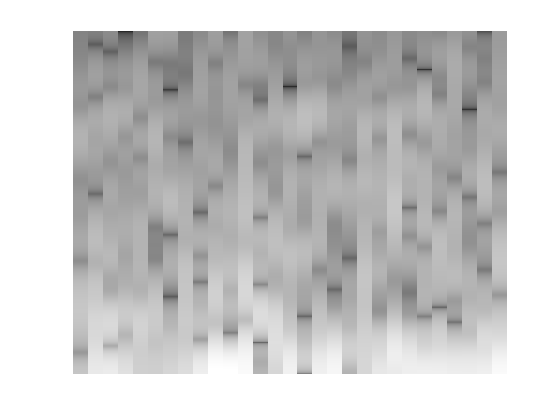

im = im(:,:,1) =

    0.5245    0.5077    0.5130    0.5113    0.5114    0.5114    0.5118    0.5081    0.4993    0.5010    0.5024    0.5029    0.5028    0.5028    0.5013    0.5247    0.5399    0.5389    0.5432    0.5432    0.5432    0.5453    0.5378    0.2290    0.1625    0.1705    0.1705    0.1705    0.1705    0.1679    0.1834    0.4253    0.4607    0.4561    0.4561    0.4566    0.4526    0.4442    0.5181    0.6339    0.6305    0.6302    0.6302    0.6304    0.6256    0.6237    0.6240    0.6247    0.6247    0.6247    0.6247    0.6243    0.6259    0.6170    0.5144    0.4826    0.4849    0.4850    0.4850    0.4847    0.4805    0.5015    0.5441    0.5465    0.5464    0.5464    0.5464    0.5464    0.5443    0.5911    0.6226    0.6210    0.6208    0.6208    0.6209    0.6202    0.6191    0.5080    0.4502    0.4524    0.4525    0.4525    0.4525    0.4489    0.4811    0.6289    0.6422    0.6366    0.6369    0.6369    0.6370    0.6374    0.6224    0.5685    0.5634    0.5656    0.5655    0.5655  

epochTable = struct2table(data.epoch);
eventIdx1 = epochTable{:, 3} == 1;
eventIdx2 = epochTable{:, 3} == 2;
t = data.times';
y = zeros(length(data.data(1, :, 1)), length(epochTable.event));

for i=1:length(epochTable.event)
    y(:, i) = data.data(1, :, i)';
    pspectrum(y(:, i), "spectrogram")
    colormap('gray')
    axis off
    colorbar off
    title('')
    if (eventIdx1(i) == 1)
        saveas(gcf, "Images/T0/"+i+".jpg");
        im = imread("Images/T0/"+i+".jpg");
        im = RemoveWhiteSpace(im);
        im = imresize(im, [224, 224]);
        imwrite(im, "Images/T0/"+i+".jpg");
    else
        saveas(gcf, "Images/T1/"+i+".jpg");
        im = imread("Images/T1/"+i+".jpg");
        im = RemoveWhiteSpace(im);
        im = imresize(im, [224, 224]);
        imwrite(im, "Images/T1/"+i+".jpg");
    end
end

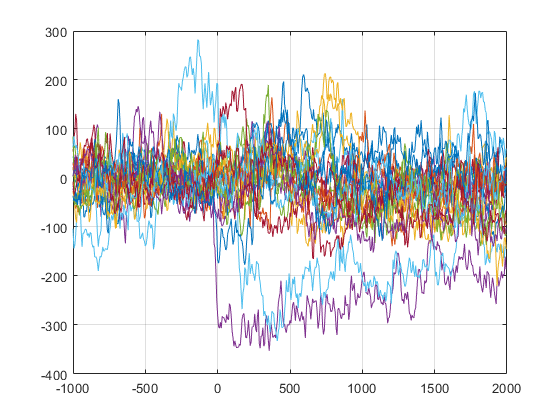

plot(t, y), grid

## Deep Learning

ds = imageDatastore("Images\", "IncludeSubfolders",true, 'LabelSource',"foldernames")

ds =   ImageDatastore with properties:

                       Files: {
                              ' ...\WorkSpace\Images\T0\1.jpg';
                              ' ...\WorkSpace\Images\T0\11.jpg';
                              ' ...\WorkSpace\Images\T0\12.jpg'
                               ... and 19 more
                              }
                     Folders: {
                              ' ...\WorkSpace\Images'
                              }
                      Labels: [T0; T0; T0 ... and 19 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


[train, test] = splitEachLabel(ds, 0.6)

train =   ImageDatastore with properties:

                       Files: {
                              ' ...\WorkSpace\Images\T0\1.jpg';
                              ' ...\WorkSpace\Images\T0\11.jpg';
                              ' ...\WorkSpace\Images\T0\12.jpg'
                               ... and 10 more
                              }
                     Folders: {
                              ' ...\WorkSpace\Images'
                              }
                      Labels: [T0; T0; T0 ... and 10 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


test =   ImageDatastore with properties:

                       Files: {
                              ' ...\WorkSpace\Images\T0\21.jpg';
                              ' ...\WorkSpace\Images\T0\3.jpg';
                              ' ...\WorkSpace\Images\T0\5.jpg'
                               ... and 6 more
                              }
                     Folders: {
                              ' ...\WorkSpace\Images'
                              }
                      Labels: [T0; T0; T0 ... and 6 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


options = trainingOptions("sgdm", "InitialLearnRate",0.001, "Plots","training-progress")

options =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-03
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 30
               MiniBatchSize: 128
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: []
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirection: 'right'
 

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:04 |       30.77% |       1.8260 |          0.0010 |


|      30 |          30 |       00:00:58 |      100.00% |       0.0240 |          0.0010 |
|========================================================================================|


net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


preds = 9×1 categorical array
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 


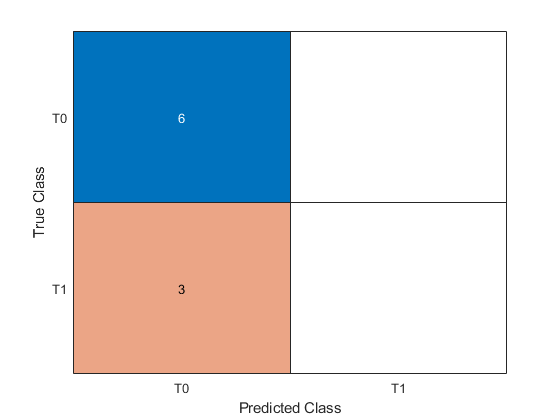

net = trainNetwork(train, lgraph_1, options)